close all
clear

load ws_steak.mat

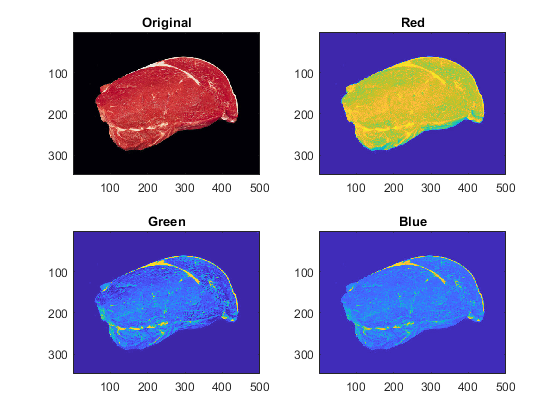

s1=imread('steak01.jpg');
s2=imread('steak02.jpg');

s1_unf= double(reshape(s1,348*500,3));
s2_unf = double(reshape(s2,341*431,3));

figure
for i=0:3
    subplot(2,2,i+1)
    if i == 0
        imagesc(s1)
        title("Original")
    else
        imagesc(s1(:,:,i))
        if i == 1
            title("Red")
        elseif i == 2
            title("Green")
        else
            title("Blue")
        end
    end
end

evaSqEuclidean = evalclusters(s1_unf, 'kmeans','silhouette','KList',3, 'Distance','sqEuclidean');
evaManhattan = evalclusters(s1_unf, 'kmeans','silhouette','KList',3, 'Distance','cityblock');
evaSqEuclideanAutoscale = evalclusters(s1_unf_autoscale.data, 'kmeans','silhouette','KList',3, 'Distance','sqEuclidean');
evaManhattanAutoscale = evalclusters(s1_unf_autoscale.data, 'kmeans','silhouette','KList',3, 'Distance','cityblock');
eva_t = [evaSqEuclidean.CriterionValues, evaManhattan.CriterionValues, evaSqEuclideanAutoscale.CriterionValues, evaManhattanAutoscale.CriterionValues];

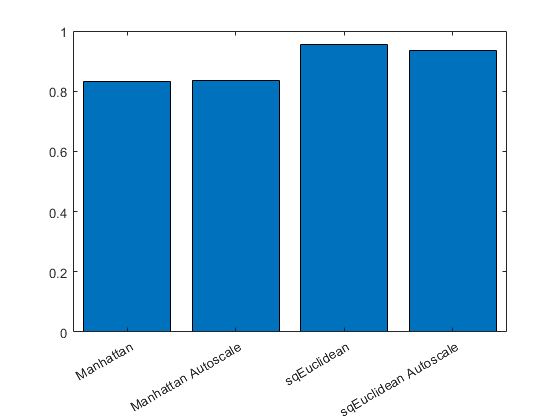

name = categorical({'sqEuclidean';'Manhattan'; 'sqEuclidean Autoscale'; 'Manhattan Autoscale'}); 
figure
bar(name,eva_t)

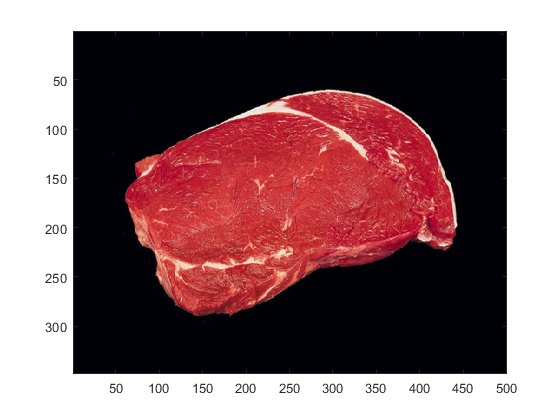

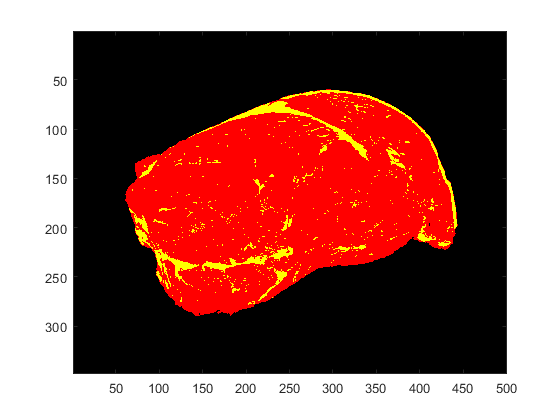

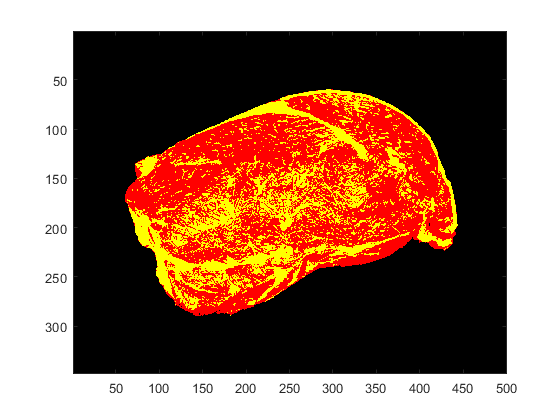

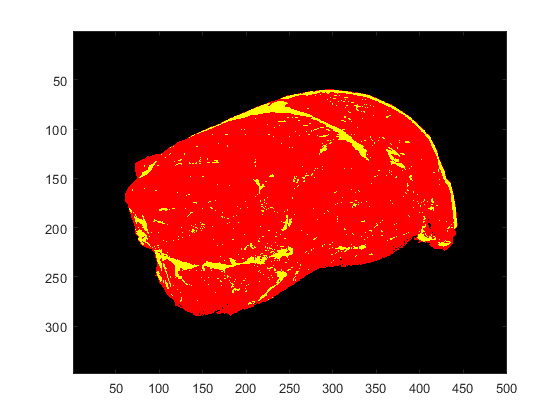

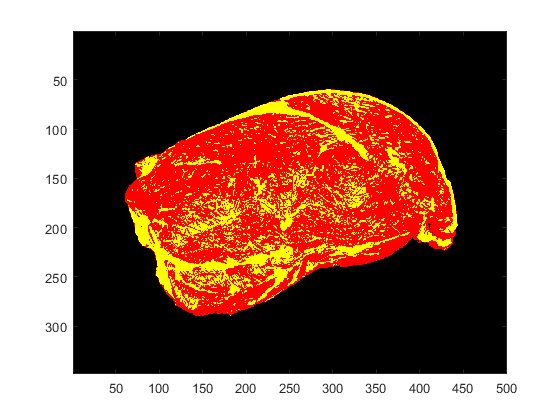

% K-Means calcolato con le due distanze
idxSqEuclide = kmeans(s1_unf, 3, "Distance","sqeuclidean");
idxManhattan = kmeans(s1_unf, 3, "Distance", "cityblock");
idxSqEuclideAutoscale = kmeans(s1_unf_autoscale.data, 3, "Distance","sqeuclidean");
idxManhattanAutoscale = kmeans(s1_unf_autoscale.data, 3, "Distance", "cityblock");

% Evidenziamo il grasso
idxKMeans = [idxSqEuclide, idxManhattan, idxSqEuclideAutoscale, idxManhattanAutoscale];

clear num_class_grasso;
figure
imagesc(uint8(reshape(s1_unf, 348, 500,3)));

kmeans_img = double(reshape(s1,348*500,3));

pixel_grasso = [];
for i=1:4
    num_class_grasso = 0;
    
    len_class1 = 0;
    len_class2 = 0;
    len_class3 = 0;
    idx = idxKMeans(:,i);
    
    for j = 1:length(idx)
        if idx(j) == 1
            len_class1 = len_class1 + 1;
        elseif idx(j) == 2
            len_class2 = len_class2 + 1;
        else
            len_class3 = len_class3 + 1;
        end
    end
    
    
[~, classe_grasso] = min([len_class1 len_class2 len_class3]);
[~, classe_sfondo] = max([len_class1 len_class2 len_class3]);
    
    for k = 1:length(idx)
        if idx(k) == classe_sfondo
            kmeans_img(k, 1) = 0;
            kmeans_img(k, 2) = 0;
            kmeans_img(k, 3) = 0;  
    
        elseif idx(k) == classe_grasso
            kmeans_img(k, 1) = 255;
            kmeans_img(k, 2) = 255;
            kmeans_img(k, 3) = 0;
            
            if i == 1
                num_class_grasso = num_class_grasso + 1;
                pixel_grasso(num_class_grasso, 1) = s1_unf(k,1);
                pixel_grasso(num_class_grasso, 2) = s1_unf(k,2);
                pixel_grasso(num_class_grasso, 3) = s1_unf(k,3); 
            end
        else
            kmeans_img(k, 1) = 255; % carne
            kmeans_img(k, 2) = 0;
            kmeans_img(k, 3) = 0;
        end
    end
    
    figure
    img_from_clustering = (reshape(kmeans_img, 348, 500, 3));
    imagesc(img_from_clustering)
end

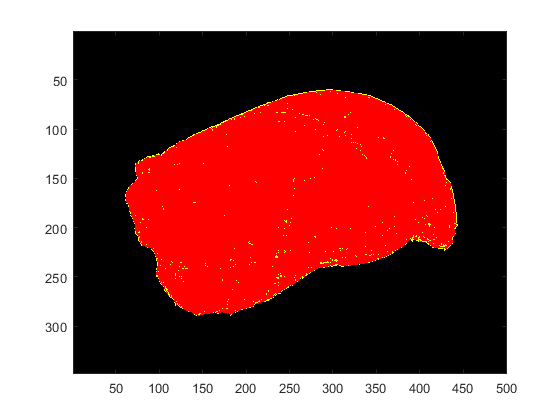

% Cluster DB
dbscan_img = double(reshape(s1,348*500,3));


for i=1:length(class_DBSCAN)
    if cell2str(class_DBSCAN(i)) == "Cluster 1" % sfondo
        dbscan_img(i, 1) = 0;
        dbscan_img(i, 2) = 0;
        dbscan_img(i, 3) = 0;
    elseif cell2str(class_DBSCAN(i)) == "Cluster 3" % carne
        dbscan_img(i, 1) = 255;
        dbscan_img(i, 2) = 0;
        dbscan_img(i, 3) = 0;
    else % grasso -> raggruppo tutti gli altri cluster
        dbscan_img(i, 1) = 255;
        dbscan_img(i, 2) = 255;
        dbscan_img(i, 3) = 0;        
    end
end

figure
img_from_dbclustering = (reshape(dbscan_img, 348, 500, 3));
imagesc(img_from_dbclustering)

epsilon = 3;
minpts = 4;
idx_dbscan = dbscan(s1_unf,epsilon,minpts);

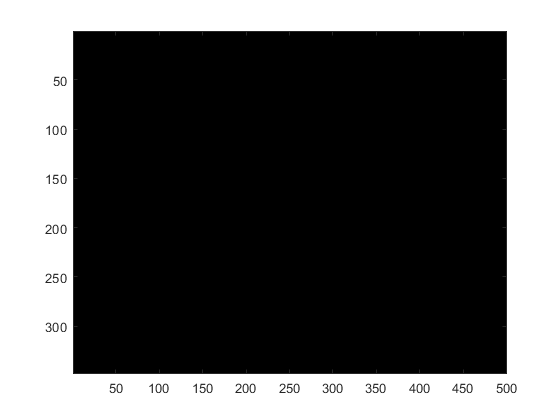


dbscan_img = double(reshape(s1,348*500,3));


for i=1:length(idx)
    if idx == 1 % sfondo
        dbscan_img(i, 1) = 0;
        dbscan_img(i, 2) = 0;
        dbscan_img(i, 3) = 0;
    elseif idx == 3 % carne
        dbscan_img(i, 1) = 255;
        dbscan_img(i, 2) = 0;
        dbscan_img(i, 3) = 0;
    else % grasso -> raggruppo tutti gli altri cluster
        dbscan_img(i, 1) = 255;
        dbscan_img(i, 2) = 255;
        dbscan_img(i, 3) = 0;        
    end
end

figure
img_from_dbclustering = (reshape(dbscan_img, 348, 500, 3));
imagesc(img_from_dbclustering)

kmeans_img = double(reshape(s2,341*431,3));
for i = 1:length(kmeans_img)
   if Q_predicted(i, 1) < 754.0255  && T2_predicted(i, 1) < 3.8426
       kmeans_img(i, 1) = 255;
       kmeans_img(i, 2) = 255;
       kmeans_img(i, 3) = 0;
   end
end

figure
img_from_clustering = (uint8(reshape(kmeans_img, 341, 431, 3)));
imagesc(img_from_clustering)